# Laboratorio di Automatica (prova del 12 Luglio 2019)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

July 12, 2019

Dept. of Information Engineering, University of Padova

## Esercizio 3

In Fig. 3 è riportato lo schema di controllo di posizione di un motore elettrico a corrente continua che fa uso di un disturbance observer (DOB).

Il motore ha funzione di trasferimento:


$$P(s)\,=\, \frac{Y(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


da ingresso in tensione $u$ $[V]$ ad uscita in posizione $y$ $[\mathrm{rad}]$.

Il controllore di velocità $C(z)$ è la versione discretizzata, con il metodo di Eulero in Avanti (Forward Euler), della seguente rete anticipatrice a tempo continuo:


$$C(s)\,=\,\frac{U(s)}{E(s)}\,=\, \;k\,\left(\frac{1+\tau\,s}{1+\alpha\,\tau\,s}\right)\qquad\quad\text{con}\qquad\quad \alpha=0.31\,,\qquad\tau=0.029\,,\qquad k = 14.3$$
  

con ingresso l'errore di posizione $e\,[\mathrm{rad}]$ ed uscita la tensione di comando $u\,[\mathrm{V}]$.

Nel DOB, $P_n(z)$ rappresenta la versione discretizzata, con il metodo esatto, della funzione di trasferimento nominale a tempo continuo $P_n(s)$ dell'impianto da controllare, che nel seguito verrà assunta pari a $P(s)$. Invece, $Q(z)$ è la versione discretizzata, con il metodo di Eulero in Avanti (Forward Euler), del segeunte filtro passa-basso a tempo continuo:


$$Q(s) \,=\, \frac{\omega_c^2}{s^2 + 2\delta\omega_c s + \omega_c^2}\qquad\text{con}\qquad \omega_c = 2\pi\,5\,\mathrm{rad/s}\,,\quad \delta = 1/\sqrt{2}$$


necessario per la fisica realizzabilità del DOB, e per la reiezione del rumore di misura.

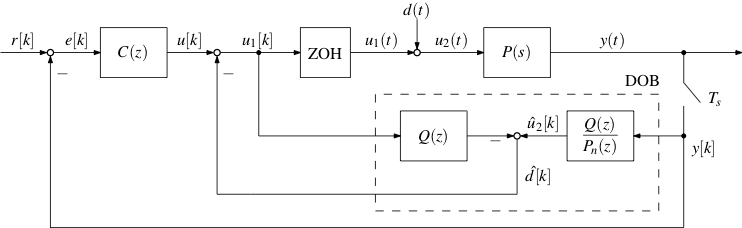

**Figura 3**: Sistema di controllo di posizione a tempo discreto con DOB.

Considerando un tempo di campionamento $T_s = 10\,\mathrm{ms}$, si svolgano i seguenti punti: 

1) Realizzare uno schema Simulink del sistema di controllo di Fig. 3. Si assuma che:

- la tensione $u_1(t)$ sia fornita da un DAC (digital-to-analog converter) a 10 bit e range d uscita pari a $\pm\,10\,V$

- la misura di posizione $y[k]$ sia fornita da un encoder con risoluzione pari a $2000\,\mathrm{ppr}$ (*pulses-per-rotation*, ovvero impulsi-per-giro)

*Nota*: per simulare sia il campionatore che lo Zero-Order Holder (ZOH), si faccia ricorso al blocco `Discrete `$\rightarrow$` Zero-Order Hold` della libreria di blocchi del Simulink.

*Soluzione*.

%   conversion gains
deg2rad = pi/180;
rad2deg = 180/pi;

%   sampling time
Ts = 10e-3;

%   motor params
km = 5.2;
Tm = 0.03;

numP = km;
denP = [Tm, 1, 0];

%   controller params
a = 0.31;
tau = 0.029;
k = 14.3;

%   controller discretization (Forward Euler)
z = tf('z', Ts);
q = (z-1)/Ts;
sysC = minreal( k*(1 + tau*q)/(1 + a*tau*q) );
[numC, denC] = tfdata(sysC, 'v');

%   DOB params - low-pass filter Q(z)
wc = 2*pi*5;
sysQ = minreal( wc^2/(q^2 + 2/sqrt(2)*wc*q + wc^2) );
[numQ, denQ] = tfdata(sysQ, 'v');

%   DOB params - nominal plant Pn(z)
sysPn = tf(numP, denP);
sysPn = c2d(sysPn, Ts, 'zoh');
[numPn, denPn] = tfdata(sysPn, 'v');

%   DOB params - filter H(z)=Q(z)/Pn(z)
sysH = minreal( sysQ/sysPn );
[numH, denH] = tfdata(sysH, 'v');

%    open Simulink model
open_system('ex3_sim1')

2) Simulare la risposta del sistema di controllo con un riferimento di posizione $r$ a gradino di ampiezza $A_r = 50\,\mathrm{deg}$ applicato in $t_r = 0\,\mathrm{s}$, e un disturbo $d$ a gradino di ampiezza $A_d = 5\,\mathrm{V}$, applicato in $t_d = 1\,\mathrm{s}$. Si imposti un tempo finale di simulazione adeguato (es. $2\,\mathrm{s}$).

*Soluzione*.

%    set reference params (amplitude & start time)
Ar = 50*deg2rad;  t0r = 0;  

%    set disturbance params (amplitude & start time)
Ad = 5;  t0d = 1;  

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.01', 'StopTime','2');

%    run simulation
sim('ex3_sim1');

3)  Con riferimento alla simulazione eseguita al punto 2, mostrare in una figura Matlab gli andamenti dei seguenti segnali: 	

- plot 1: posizione misurata $y[k]$ e riferimento $r[k]$, entrambi espressi in $[\mathrm{deg}]$

- plot 2: errore di inseguimento $e[k]$, espresso in $[\mathrm{deg}]$

- plot 3: disturbo $d(t)$ e stima del disturbo $\hat{d}[k]$, entrambi espressi in $[\mathrm{V}]$

Verificare che grazie alla presenza del DOB, il sistema di controllo è in grado di reiettare completamente il disturbo di carico costante, anche in assenza dell'azione integrale nel controllore.		

*Soluzione*.	

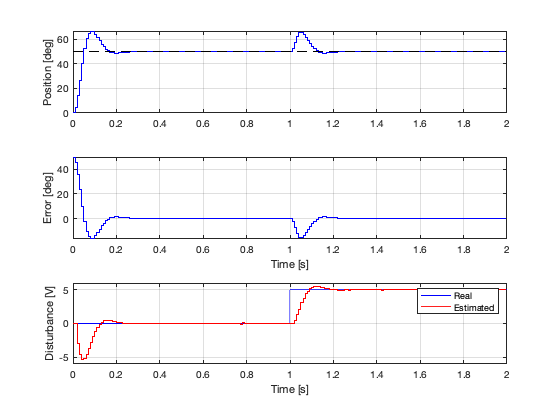

%   extract signas
t = simres.time;
th = simres.signals(1).values(:,1);
th_ref = simres.signals(1).values(:,2);
e = simres.signals(2).values;
d = simres.signals(3).values;
d_est = simres.signals(4).values;

%   plot results
figure;
subplot(3,1,1);
stairs(t, th, 'b');
hold on;
stairs(t, th_ref, 'k--');
grid on;
ylabel('Position [deg]');

subplot(3,1,2);
stairs(t, e, 'b');
grid on;
ylabel('Error [deg]');
xlabel('Time [s]');

subplot(3,1,3);
plot(t, d, 'b');
hold on;
stairs(t, d_est, 'r');
grid on;
ylabel('Disturbance [V]');
xlabel('Time [s]');
legend('Real', 'Estimated');
ylim([-6, 6]);